3-1

%a
a = [0 1 0; 0 0 1; -3 -2 -5];
b  = [0; 0;1];
c = [1 0 0];
d = [0];
sys_ss = ss(a,b,c,d);
sys_tf = tf(sys_ss)

sys_tf =
 
            1
  ---------------------
  s^3 + 5 s^2 + 2 s + 3
 
Continuous-time transfer function.



%b
x0 = [0;-1;1];
t = 0:0.1:10;
u=0*t; %zero input
[y,t,x] = lsim(sys_ss, u, t, x0)

y =          0
   -0.0954
   -0.1831
   -0.2644
   -0.3399
   -0.4101
   -0.4750
   -0.5346
   -0.5890
   -0.6379


t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


x =          0   -1.0000    1.0000
   -0.0954   -0.9126    0.7685
   -0.1831   -0.8430    0.6376
   -0.2644   -0.7831    0.5679
   -0.3399   -0.7282    0.5352
   -0.4101   -0.6753    0.5240
   -0.4750   -0.6230    0.5249
   -0.5346   -0.5702    0.5318
   -0.5890   -0.5165    0.5410
   -0.6379   -0.4620    0.5502


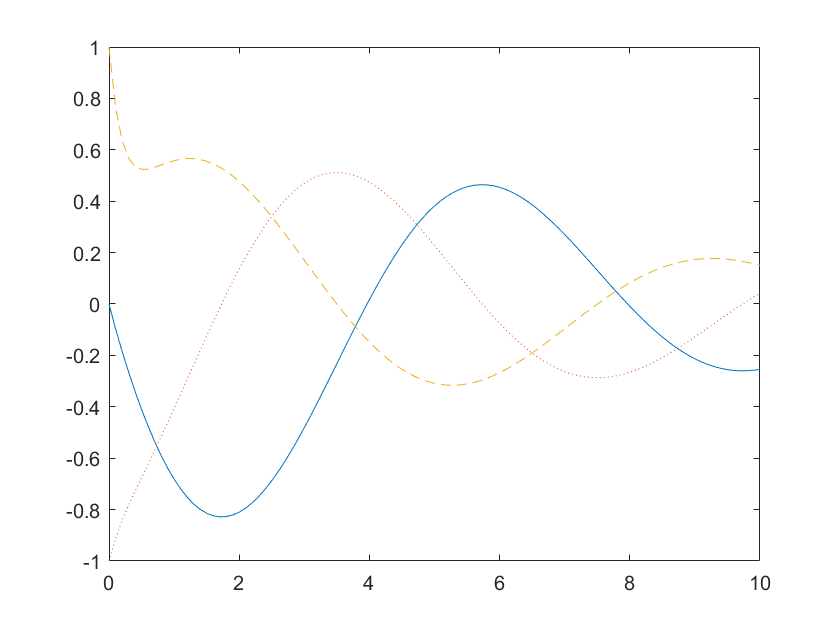

plot(t,x(:,1),t,x(:,2),':',t,x(:,3),'--');

x_t = x(length(t),:)

x_t =    -0.2545    0.0418    0.1500


%c
dt = 10;
Phi = expm(a*dt)

Phi =     0.0853    0.3183    0.0637
   -0.1911   -0.0421   -0.0003
    0.0010   -0.1905   -0.0405


x_t = Phi*x0

x_t =    -0.2545
    0.0418
    0.1500


3-2

%a
a1 = [0 1 0; 0 0 1; -4 -5 -8];
b1 = [0;0;4];
c1 = [1 0 0];
d1 = [0];
sys_ss = ss(a1,b1,c1,d1);
sys_tf = tf(sys_ss)

sys_tf =
 
            4
  ---------------------
  s^3 + 8 s^2 + 5 s + 4
 
Continuous-time transfer function.




%b
a2 = [ 0.5000 0.5000 0.7071;-0.5000 -0.5000 0.7071;-6.3640 -0.7071 -8.0000];
b2 = [0;0;4];
c2 = [0.7071 -0.7071 0];
d2 = [0];
sys_ss = ss(a2,b2,c2,d2);
sys_tf = tf(sys_ss)

sys_tf =
 
            4
  ---------------------
  s^3 + 8 s^2 + 5 s + 4
 
Continuous-time transfer function.



两者的传递函数相同，说明对于同一转移函数，可能有不同的状态空间模型。

3-3

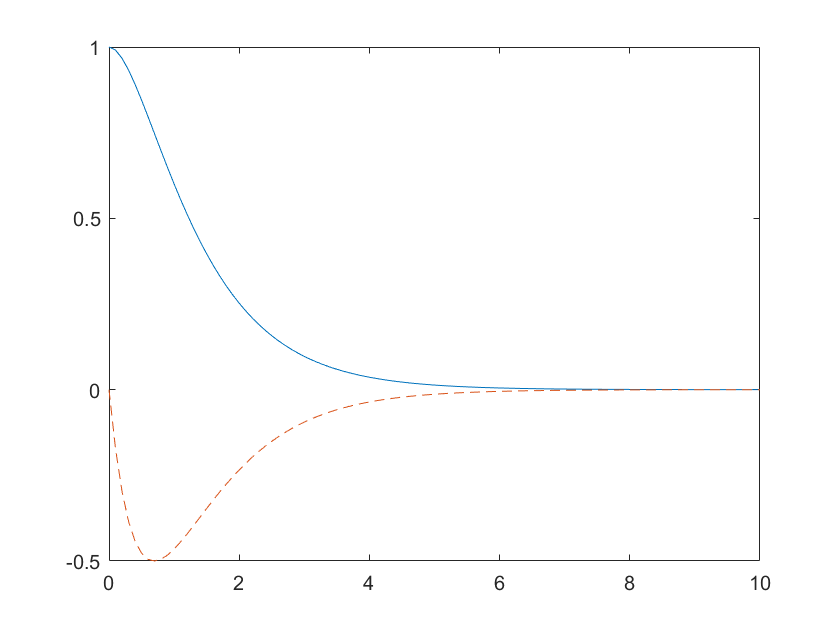

a = [0 1;-2 -3];
b = [0;1];
c = [1 0];
d = [0];
sys = ss(a,b,c,d);
x0 = [1;0];
t = [0:0.1:10];
u = 0*t;
[y,t,x] = lsim(sys,u,t,x0);
plot(t,x(:,1),t,x(:,2),'--')